problem 1

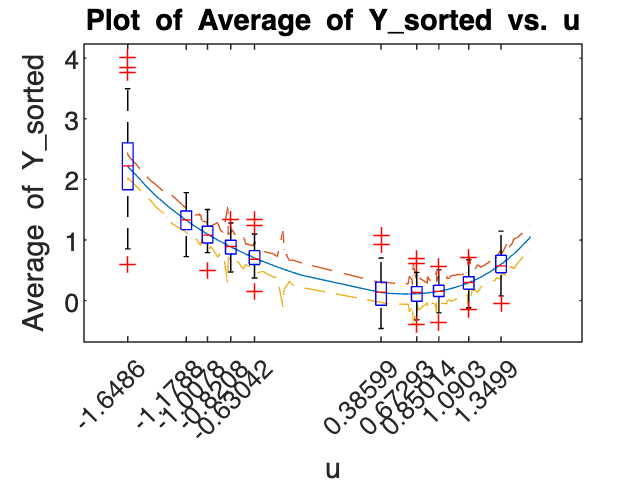

clc
clear

% Define your parameters
theta = [0.3, -0.5, 0.5, 0.2, 0.4];
u_mean = 1;
u_variance = 0.12;

% Initialize a matrix to store all the Y values
Y_all = zeros(100, 100);


% Generate half of u values from N(u_mean, u_variance)
half_size = 100/2;
u_half1 = -u_mean + sqrt(u_variance) * randn(half_size, 1);

% Generate half of u values from N(-u_mean, u_variance)
u_half2 = u_mean + sqrt(u_variance) * randn(half_size, 1);
u = [u_half1; u_half2];

% Generate X matrix
X = [ones(100,1), u, u.^2/2, u.^3/3, u.^4/4];

for i = 1:100
    % Generate noise N(mu, sigma)
    N = randn(100, 1);

    % Calculate Y
    Y = X * theta' + N;
    
    % Store Y in the matrix
    Y_all(:, i) = Y;
end

% Perform LS estimation
theta_hat_LS = (X' * X)^-1 * X' * Y_all;

 % Calculate Y_hat
 Y_hat = X * theta_hat_LS;

% Sort X
[X_sorted, idx] = sort(X(:, 2)); % Sorting according to the second column (u)
%X_sorted = X(idx, :);
 
% Sort Y according to the indexes of sorted X
Y_sorted = Y_hat(idx,:);
 
% Calculate the average of each column of Y_sorted
Y_avg = mean(Y_sorted, 2); 
 
% Calculate the variance along columns (variance of each row)
variance_along_columns = (std(Y_hat, 0, 2));

% Plot the average of Y_sorted with respect to u
figure;
plot(X_sorted, Y_avg, '-');
xlabel('u');
ylabel('Average of Y\_sorted');
title('Plot of Average of Y\_sorted vs. u');
hold on
plot(X_sorted, Y_avg + variance_along_columns , '--');
plot(X_sorted, Y_avg - variance_along_columns , '--');
%scatter(u(idx, :),Y_sorted)
%errorbar(u(idx(1:10:end), :), Y_sorted(1:10), variance_along_columns(1:10), 'o-');
% boxplot(Y_sorted(1:10, :).')
% xticklabels(X_sorted.');
% Create the boxplot
hBoxPlot = boxplot(Y_sorted(1:10:100, :).', 'Positions', X_sorted(1:10:100));

% Set the x-tick labels to correspond to the sorted X values
set(gca, 'xticklabel', arrayfun(@num2str, X_sorted(1:10:100), 'UniformOutput', false));



%xticks(X_sorted(1:10, :));
hold off

test for Y_sorted

% Y_sorted
% Y_sorted(1:10)
% Y_sorted(1:10, :)
Y_sorted(1:10, :).'

ans =     1.8226    1.8222    1.7131    1.6677    1.6311    1.5658    1.5626    1.5498    1.5292    1.3827
    1.3984    1.4020    1.7195    1.7554    1.7708    1.7781    1.7779    1.7768    1.7737    1.7158
    2.4359    2.4302    1.7890    1.6571    1.5693    1.4405    1.4349    1.4131    1.3796    1.1894
    0.8961    0.9022    1.4641    1.5407    1.5805    1.6186    1.6196    1.6230    1.6264    1.5919
    2.3360    2.3304    1.7492    1.6419    1.5741    1.4807    1.4768    1.4620    1.4397    1.3296
    3.3071    3.3010    2.5539    2.3758    2.2505    2.0546    2.0458    2.0108    1.9562    1.6163
    1.6895    1.6905    1.7168    1.6961    1.6751    1.6312    1.6289    1.6196    1.6040    1.4827
    2.1942    2.1880    1.5247    1.3965    1.3135    1.1957    1.1907    1.1713    1.1420    0.9853
    2.2982    2.2959    1.9848    1.9024    1.8423    1.7445    1.7400    1.7220    1.6935    1.5068
    1.5830    1.5845    1.6905    1.6912    1.6855    1.6660    1.6648    1.6598    1

Y_sorted(3, :).'

ans =     1.7131
    1.7195
    1.7890
    1.4641
    1.7492
    2.5539
    1.7168
    1.5247
    1.9848
    1.6905


test for X_sorted

%X_sorted
%X_sorted(1:10, :)

problem 2

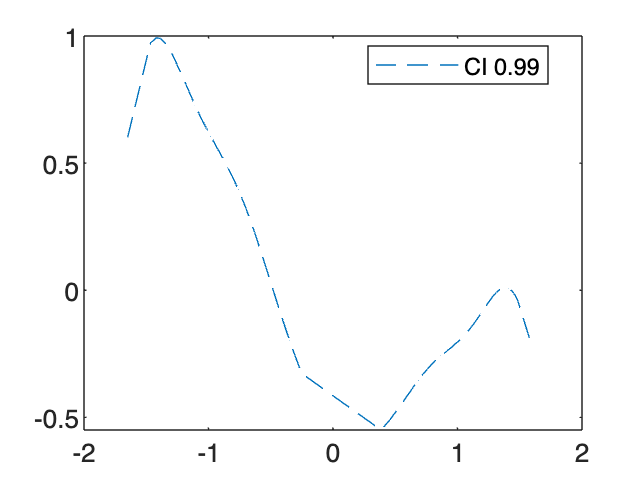

% Calculate the standard deviation along columns
std_dev = std(Y_sorted, 0, 2);

% Calculate confidence intervals for 90%, 95%, and 99%
alpha = [0.1, 0.05, 0.01];
for i = 1:length(alpha)
    z = abs(norminv(alpha(i)/2));
    CI = z * std_dev;
    plot(X_sorted, Y_avg + CI , '--', 'DisplayName', ['CI ' num2str(1-alpha(i))]);
    plot(X_sorted, Y_avg - CI , '--', 'DisplayName', ['CI ' num2str(1-alpha(i))]);
end
legend('Location', 'best');